z = -0.2000

p = -0.5000

k = 1

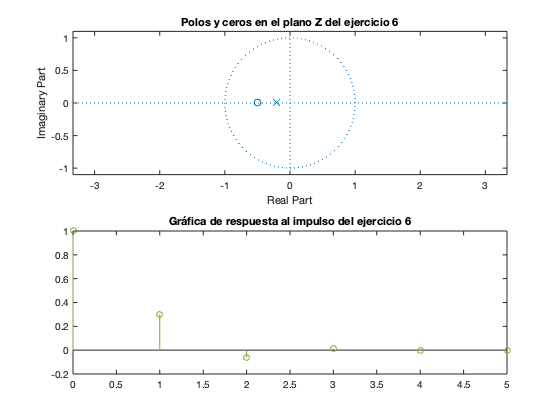

% %PRIMER SISTEMA
% num = [4, -5];
% den = [2, -5, 2];
% tfz(num, den, 1)
% 
% %SEGUNDO SISTEMA
% num = [2];
% den = [1, -1];
% tfz(num, den, 2)
% 
% %TERCER SISTEMA
% num = [2];
% den = [1, -3/4, 1/8];
% tfz(num, den, 3)
% 
% %CUARTO SISTEMA
% num = [4, 3];
% den = [4, -3, 2, -1];
% tfz(num, den,4)
% 
% %QUINTO SISTEMA
% num = [1];
% den = [1, 0, -1i];
% tfz(num, den,5)
% 
% %SEXTO SISTEMA
% num = [2, 1];
% den = [1, -2, 3];
% tfz(num, den,6)


num = [1, 0.2];
den = [1, 0.5];
tfz(num, den,6)

function [] = tfz(num, den, int)
%z = ceros; p = polos; k = ganancias
[z,p,k] = tf2zp(num, den)


[h,t] = impz(num, den);
figure
subplot(2,1,1)
    zplane(z, p)
    title("Polos y ceros en el plano Z del ejercicio " + int)
subplot(2,1,2)
    stem(t,h, 'color', [0.4660, 0.6740, 0.1880]	)
    title("Gráfica de respuesta al impulso del ejercicio " + int)
end